# **This MATLAB Live Script compares analytic and numerical**

# **solutions of CRPS of **$P=N\left(\mu ,\sigma \mathrm{²}\right)$** of Vrugt, WRR (2024)**

**Note: the derivation below was added months after MATLAB code was written**

$\tau$: tau, $\mu$: mu, $\omega$: omega

**Quantile form of the CRPS [in negative orientation!]**


$$\mathrm{CRPS}\left(P,\omega \right)=\omega \left(2F\left(\omega \right)-1\right)-2\int_0^1 \tau F^{-1} \left(\tau \right)\mathrm{d}\tau +2\int_{F\left(\omega \right)}^1 F^{-1} \left(\tau \right)\mathrm{d}\tau$$


**Quantile function **$F^{-1} \left(\tau \right)$ **(= inverse CDF)** **of normal distribution **$N\left(\mu ,\sigma^2 \right)$** with mean **$\mu$ **and variance** $\sigma \mathrm{²}$ 


$$F^{-1} \left(\tau \right)=\mu +\sqrt{2}\sigma {\mathrm{erf}}^{-1} \left(2\tau -1\right)$$
 

**Lets first get an analytic expression for the first integral of the CRPS**


$$\int_0^1 \tau F^{-1} \left(\tau \right)\mathrm{d}\tau$$


**Integration by parts **


$$\int u\;\mathrm{dv}=uv-\int v\;\mathrm{du}\;$$


if $u=\tau$, **then** $\mathrm{du}=1$

if $\mathrm{dv}=F^{-1} \left(\tau \right)$, **then** 

     
$$v=\int \left(\mu +\sqrt{2}{\sigma \mathrm{erf}}^{-1} \left(2\tau -1\right)\right)\mathrm{d}\tau$$


   
$$\;\;\;\;\;=\int \mu \mathrm{d}\tau +\int \sqrt{2}{\sigma \mathrm{erf}}^{-1} \left(2\tau -1\right)\mathrm{d}\tau$$
 

   
$$\;\;\;\;\;=\mu \tau -\frac{\sigma }{\sqrt{2\pi }}\exp \left(-{{\mathrm{erf}}^{-1} \left(2\tau -1\right)}^2 \right)$$
 

**Thus, for first integral we yield**


$$\begin{array}{l}
\int_0^1 \tau F^{-1} \left(\tau \right)\mathrm{d}\tau =\tau \left(\mu \tau -\frac{\sigma }{\sqrt{2\pi }}\exp \left(-{{\mathrm{erf}}^{-1} \left(2\tau -1\right)}^2 \right)\right)-\int \left(\mu \tau -\frac{\sigma }{\sqrt{2\pi }}\exp \left(-{{\mathrm{erf}}^{-1} \left(2\tau -1\right)}^2 \right)\right)\mathrm{d}\tau \\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;=\mu \tau^2 -\frac{\sigma \tau }{\sqrt{2\pi }}\exp \left(-{{\mathrm{erf}}^{-1} \left(2\tau -1\right)}^2 \right)-\int \mu \tau \;\mathrm{d}\tau +\int \frac{\sigma }{\sqrt{2\pi }}\exp \left(-{{\mathrm{erf}}^{-1} \left(2\tau -1\right)}^2 \right)\;\mathrm{d}\tau \\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;=\mu \tau^2 -\frac{\sigma \tau }{\sqrt{2\pi }}\exp \left(-{{\mathrm{erf}}^{-1} \left(2\tau -1\right)}^2 \right)-\frac{1}{2}\mu \tau^2 +\frac{\sigma \mathrm{erf}\left(\sqrt{2}{\mathrm{erf}}^{-1} \left(2\tau -1\right)\right)}{4\sqrt{\pi }}\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;=\frac{1}{2}\mu \tau^2 -\frac{\sigma \tau }{\sqrt{2\pi }}\exp \left(-{{\mathrm{erf}}^{-1} \left(2\tau -1\right)}^2 \right)+\frac{\sigma \mathrm{erf}\left(\sqrt{2}{\mathrm{erf}}^{-1} \left(2\tau -1\right)\right)}{4\sqrt{\pi }}\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;={\left\lbrack \frac{1}{2}\mu \tau^2 -\frac{\sigma \tau }{\sqrt{2\pi }}\exp \left(-{{\mathrm{erf}}^{-1} \left(2\tau -1\right)}^2 \right)+\frac{\sigma \mathrm{erf}\left(\sqrt{2}{\mathrm{erf}}^{-1} \left(2\tau -1\right)\right)}{4\sqrt{\pi }}\right\rbrack }_0^1 \\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;=\left(\frac{1}{2}\mu -\frac{\sigma }{\sqrt{2\pi }}\exp \left(-\infty^2 \right)+\frac{\sigma \mathrm{erf}\left(\sqrt{2}\infty \right)}{4\sqrt{\pi }}\right)-\left(\frac{\sigma \mathrm{erf}\left(\sqrt{2}\left(-\infty \right)\right)}{4\sqrt{\pi }}\right)\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;=\frac{1}{2}\mu +\frac{\sigma }{4\sqrt{\pi }}+\frac{\sigma }{4\sqrt{\pi }}=\frac{1}{2}\mu +\frac{\sigma }{2\sqrt{\pi }}
\end{array}$$


**Now the second integral of the CRPS quantile decomposition**


$$\begin{array}{l}
\int_{F\left(\omega \right)}^1 F^{-1} \left(\tau \right)\mathrm{d}\tau ={\left\lbrack \mu \tau -\frac{\sigma }{\sqrt{2\pi }}\exp \left(-{{\mathrm{erf}}^{-1} \left(2\tau -1\right)}^2 \right)\right\rbrack }_{F\left(\omega \right)}^1 \\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;=\left(\mu -\frac{\sigma }{\sqrt{2\pi }}\exp \left(-\infty^2 \right)\right)-\left(\mu F\left(\omega \right)-\frac{\sigma }{\sqrt{2\pi }}\exp \left(-{{\mathrm{erf}}^{-1} \left(2F\left(\omega \right)-1\right)}^2 \right)\right)\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;=\mu \left(1-F\left(\omega \right)\right)+\frac{\sigma }{\sqrt{2\pi }}\exp \left(-{{\mathrm{erf}}^{-1} \left(2F\left(\omega \right)-1\right)}^2 \right)
\end{array}$$


**Now, if we insert the two integrals into the quantile form of the CRPS, we yield**


$$\begin{array}{l}
\mathrm{CRPS}\left(P,\omega \right)=\omega \left(2F\left(\omega \right)-1\right)-2\int_0^1 \tau F^{-1} \left(\tau \right)\mathrm{d}\tau +2\int_{F\left(\omega \right)}^1 F^{-1} \left(\tau \right)\mathrm{d}\tau \\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;=\omega \left(2F\left(\omega \right)-1\right)-2\left(\frac{1}{2}\mu +\frac{\sigma }{2\sqrt{\pi }}\right)+2\left(\mu \left(1-F\left(\omega \right)\right)+\frac{\sigma }{\sqrt{2\pi }}\exp \left(-{{\mathrm{erf}}^{-1} \left(2F\left(\omega \right)-1\right)}^2 \right)\right)\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;=\omega \left(2F\left(\omega \right)-1\right)-\mu -\frac{\sigma }{\sqrt{\pi }}+2\mu -2\mu F\left(\omega \right)+\frac{\sqrt{2}\sigma }{\sqrt{\pi }}\exp \left(-{{\mathrm{erf}}^{-1} \left(2F\left(\omega \right)-1\right)}^2 \right)\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;=2\left(\omega -\mu \right)F\left(\omega \right)-\omega +\mu +\frac{\sigma }{\sqrt{\pi }}\left(\sqrt{2}\exp \left(-{{\mathrm{erf}}^{-1} \left(2F\left(\omega \right)-1\right)}^2 \right)-1\right)
\end{array}$$
 

**Now, **$F\left(\omega \right)$ **is the CDF of the normal distribution evaluated at** $\omega$. **We write**, $F_N \left(\omega ,\mu ,\sigma^2 \right)$

**and**, $\frac{\sigma \sqrt{2}}{\sqrt{\pi }}\exp \left(-{{\mathrm{erf}}^{-1} \left(2F\left(\omega \right)-1\right)}^2 \right)$ **is equal to** $2\sigma^2 f_N \left(\omega ,\mu ,\sigma^2 \right)$ **where** $f_N \left(\omega ,\mu ,\sigma^2 \right)$ **is the normal PDF**

**Thus, we yield**


$$\begin{array}{l}
\mathrm{CRPS}\left(P,\omega \right)=2\left(\omega -\mu \right)F\left(\omega \right)-\omega +\mu +\frac{\sigma }{\sqrt{\pi }}\left(\sqrt{2}\exp \left(-{{\mathrm{erf}}^{-1} \left(2F\left(\omega \right)-1\right)}^2 \right)-1\right)\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;=2\left(\omega -\mu \right)F_N \left(\omega ,\mu ,\sigma^2 \right)-\omega +\mu +{2\sigma }^2 f_N \left(\omega ,\mu ,\sigma^2 \right)-\frac{\sigma }{\sqrt{\pi }}
\end{array}$$


**which in positive orientation equals [a larger CRPS is better]**

$\begin{array}{l}
\mathrm{CRPS}\left(P,\omega \right)=2\left(\mu -\omega \right)F_N \left(\omega ,\mu ,\sigma^2 \right)-2\sigma^2 f_N \left(\omega ,\mu ,\sigma^2 \right)-\mu +\omega +\frac{\sigma }{\sqrt{\pi }}\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;=\frac{\sigma }{\sqrt{\pi }}-2\sigma^2 f_N \left(\omega ,\mu ,\sigma^2 \right)-\left(\omega -\mu \right)\left(2F_N \left(\omega ,\mu ,\sigma^2 \right)-1\right)
\end{array}$            **This equals Equation I12 of paper**

**The above is a closed-form expression for the CRPS for a normal forecast CDF,**$\;P=N\left(\mu ,\sigma \mathrm{²}\right)$ **and verifying observation** $\omega$. 

**We can compare this analytic solution against a numerical solution of the CRPS**

**Reference**:

Vrugt, J. A. (2024). **Distribution-based model evaluation and diagnostics: Elicitability, propriety, and scoring rules for hydrograph functionals**. *Water Resources Research*, 60,e2023WR036710, [https://doi.org/10.1029/2023WR036710](https://doi.org/10.1029/2023WR036710)

Written by **Jasper A. Vrugt**

close all hidden; clear variables; clc

`Define parameter values of the normal distribution forecast, `$P=N\left(\mu ,\sigma \mathrm{²}\right)$

mu = 2;         % mean of normal distribution forecast
s2 = pi;        % variance of normal distribution forecast
n = 1000;       % number of measurements (w = omega)

`No need to change from here`

s = sqrt(s2);               % MATLAB uses sigma as input to normpdf/normcdf
F_N = @(w) normcdf(w,mu,s); % CDF of normal distribution
f_N = @(w) normpdf(w,mu,s); % PDF of normal distribution

`Sample ensemble from `$N\left(\mu ,\sigma \mathrm{²}\right)$` --> for numerical estimate of CRPS`

[fcst_n] = normrnd(mu,s,1000,2000);
% Now use samples to determine min/max for drawing verifying observations
r = range(fcst_n(:));
w_min = min(fcst_n(:)) - r/10; w_max = max(fcst_n(:)) + r/10;
W = unifrnd(w_min,w_max,n,1);
% Initialize some variables for aanlytic computation of CRPS
[crps_an,L,La,R,Ra] = deal(nan(n,2)); [Lt,Rt] = deal(nan(n,1));

% Loop over all measurements
for i = 1:n
    w = W(i); % unpack measurements one at a time
    % Left integral
    % Numerical estimate of left integral - upper bound
    tau = 0.9999;
    L(i,1) = tau * ( mu*tau - (2^(1/2)*s*exp(-erfinv(2*tau - 1)^2)) ...
        / (2*pi^(1/2)) ) - ( (mu*tau^2)/2 - (s*erf(2^(1/2) * ...
        erfinv(2*tau - 1)))/(4*pi^(1/2)) );
    % Analytic estimate of left integral - upper bound
    La(i,1) = mu - ( mu/2 - s/(4*pi^(1/2)));
    % Numerical estimate of left integral - lower bound
    tau = 0.0001;
    L(i,2) = tau * ( mu*tau - (2^(1/2)*s*exp(-erfinv(2*tau - 1)^2)) ...
        / (2*pi^(1/2)) ) - ( (mu*tau^2)/2 - (s*erf(2^(1/2) * ...
        erfinv(2*tau - 1)))/(4*pi^(1/2)) );
    % Analytic estimate of left integral - lower bound
    La(i,2) = - s/(4*pi^(1/2));
    % Analytic value of left integral ( should equal L(i,1) - L(i,2) )
    Lt(i,1) = mu/2 + 2*s/(4*sqrt(pi));
    % Lt(i,1) = mu - ( mu/2 - s/(4*pi^(1/2))) - ( - s/(4*pi^(1/2)));
    
    % Right integral
    % Numerical estimate of right integral - upper bound
    tau = 0.9999;
    R(i,1) = mu*tau - (2^(1/2)*s*exp(-erfinv(2*tau - 1)^2))/(2*pi^(1/2));
    % Analytic estimate of right integral - upper bound
    Ra(i,1) = mu;
    % Numerical estimate of right integral - lower bound
    tau = F_N(w);
    R(i,2) = mu*tau - (2^(1/2)*s*exp(-erfinv(2*tau - 1)^2))/(2*pi^(1/2));
    % Analytic estimate of right integral - lower bound
    Ra(i,2) = mu*F_N(w) - (2^(1/2)*s*exp(-erfinv(2*F_N(w) ...
        - 1)^2))/(2*pi^(1/2));
    % Analytic value of right integral ( should equal R(i,1) - R(i,2) )
    Rt(i,1) = mu - mu*F_N(w) + (2^(1/2)*s*exp(-erfinv(2*F_N(w) ...
        - 1)^2))/(2*pi^(1/2));
    % Now solution in paper: Equation I12
    crps_an(i,1) = s/sqrt(pi) - 2*s^2*f_N(w) - (w-mu)*(2*F_N(w) - 1);
        % = - w*(2*Fn(w) - 1) + 2 * (L(i,1)-L(i,2)) - 2 * (R(i,1)-R(i,2));
        % = - w*(2*Fn(w) - 1) + 2 * Lt(i,1) - 2 * Rt(i,1);
    % Solution from quantile formulation - without simplification
    crps_an(i,2) = - w*(2*F_N(w) - 1) - mu + 2*mu*F_N(w) + s/sqrt(pi) ...
        - 2^(1/2)*s*exp(-erfinv(2*F_N(w) - 1)^2)/sqrt(pi);
    % --> is equal to crps_an(:,1) 
end

% Compute CRPS from ensemble --> numerical estimates
[~,crps_num] = crp_score(fcst_n,W,'weib');

`PLOT RESULTS `

`Plot 1: Scatter plot CRPS from analytic solution of CRPS (Eq. I12 derived above) and CRPS from ensemble`

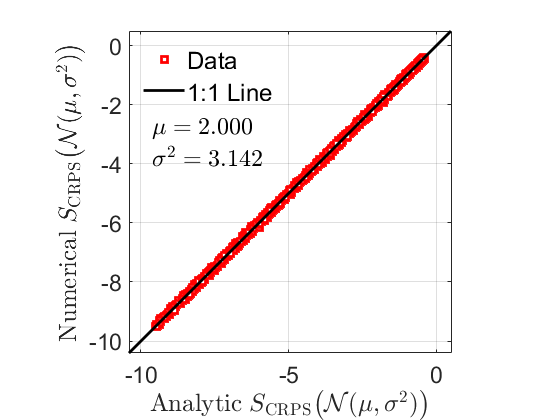

figure(1)
% Plot analytic versus numerical CRPS values
plot(crps_an(:,1),crps_num,'rs','markerfacecolor','w','linewidth',2);
xlabel(['${\rm Analytic}\; S_{\rm CRPS}\bigl(\mathcal{N}' ...
    '(\mu,\sigma^{2})\bigr)$'],'interpreter','latex','fontsize',18);
ylabel(['${\rm Numerical}\; S_{\rm CRPS}\bigl(\mathcal{N}' ...
    '(\mu,\sigma^{2})\bigr)$'],'interpreter','latex','fontsize',18);
axis square
r = range(crps_an(:,1));
xymin = min(crps_an(:,1)) - r/10; xymax = max(crps_an(:,1)) + r/10;
axis([xymin xymax xymin xymax]);
line([xymin xymax],[xymin xymax],'linewidth',2,'color','k');
legend('Data','1:1 Line','fontsize',18,'location','northwest'); 
legend boxoff
text(xymin + 0.07*(xymax - xymin),xymin + 0.7*(xymax-xymin), ...
    char(strcat('$\mu =',{' '},num2str(mu,'%5.3f'),'$')), ...
    'interpreter','latex','fontsize',18);
text(xymin + 0.07*(xymax - xymin),xymin + 0.6*(xymax-xymin), ...
    char(strcat('$\sigma^{2} =',{' '},num2str(s2,'%5.3f'),'$')), ...
    'interpreter','latex','fontsize',18);
set(gca,'fontsize',17); set(gcf,'color','w'); grid on

% Print some superificial errors to screen
max_err = max(abs(crps_num-crps_an(:,1)));
mean_err = mean(abs(crps_num-crps_an(:,1)));

`Plot 2: Scatter plot analytic and numerical CRPS (from original expression quantile form)`

figure(2)
plot(crps_an(:,2),crps_num,'rs','markerfacecolor','w','linewidth',2);
xlabel(['${\rm Analytic}\; S_{\rm CRPS}\bigl(\mathcal{N}' ...
    '(\mu,\sigma^{2})\bigr)$'],'interpreter','latex','fontsize',18);
ylabel(['${\rm Numerical}\; S_{\rm CRPS}\bigl(\mathcal{N}' ...
    '(\mu,\sigma^{2})\bigr)$'],'interpreter','latex','fontsize',18);
axis square
r = range(crps_an(:,1));
xymin = min(crps_an(:,1)) - r/10; xymax = max(crps_an(:,1)) + r/10;
axis([xymin xymax xymin xymax]);
line([xymin xymax],[xymin xymax],'linewidth',2,'color','k');
legend('Data','1:1 Line','fontsize',18,'location','northwest'); 
legend boxoff
text(xymin + 0.07*(xymax - xymin),xymin + 0.7*(xymax-xymin), ...
    char(strcat('$\mu =',{' '},num2str(mu,'%5.3f'),'$')), ...
    'interpreter','latex','fontsize',18);
text(xymin + 0.07*(xymax - xymin),xymin + 0.6*(xymax-xymin), ...
    char(strcat('$\sigma^{2} =',{' '},num2str(s2,'%5.3f'),'$')), ...
    'interpreter','latex','fontsize',18);
set(gca,'fontsize',17); set(gcf,'color','w'); grid on

% Print some superificial errors to screen
max_err = max(abs(crps_num-crps_an(:,2))); 
mean_err = mean(abs(crps_num-crps_an(:,2)));